filelist = [ "data_21-Mar-2025_09-26-10.mat" ,
"data_21-Mar-2025_09-28-59.mat" ,
"data_21-Mar-2025_09-32-07.mat" ,
"data_21-Mar-2025_09-34-30.mat" ,
"data_21-Mar-2025_09-37-20.mat" ,
"data_21-Mar-2025_09-42-10.mat" ,
"data_21-Mar-2025_09-43-30.mat" ,
"data_21-Mar-2025_09-51-00.mat" ,
"data_21-Mar-2025_09-52-42.mat" ,
"data_21-Mar-2025_09-55-40.mat" ,
"data_21-Mar-2025_10-02-58.mat" ,
"data_21-Mar-2025_10-09-11.mat" ,
"data_21-Mar-2025_10-10-37.mat" ,
"data_21-Mar-2025_10-12-01.mat" ,
"data_21-Mar-2025_10-17-54.mat" ,
"data_21-Mar-2025_10-21-14.mat" ,
"data_21-Mar-2025_10-24-43.mat" ,
"data_21-Mar-2025_10-29-46.mat" ,
"data_21-Mar-2025_10-36-06.mat" ];

exp_id = 19

exp_id = 19

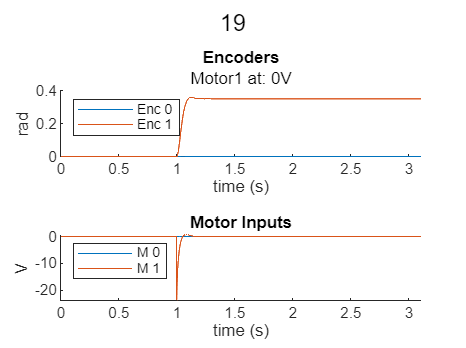

filename = "lab3/data/pid/" + filelist(exp_id);
load(filename,"data")

smartPlotEncVoltage(data,exp_id,false);

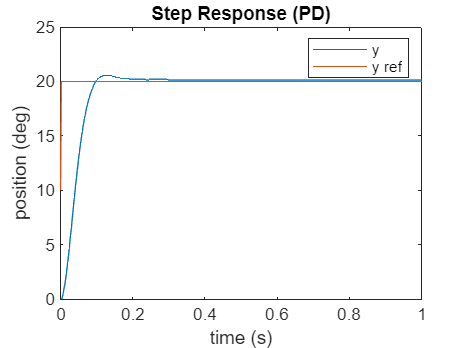


t = data(1,:)-1;
y = rad2deg(data(3,:));
y_ref = 20*(0.5 + 0.5*sign(t));

figure
plot(t,y)
hold on
plot(t,y_ref)
legend("y","y ref")
hold off
xlim([0 1])
title("Step Response (PD)")
ylabel("position (deg)")
xlabel("time (s)")